datadir = 'C:\Users\bgrau\Dropbox (Dartmouth College)\2023_Graul_EEE\Data\processed\sub-01\imgview';
filename = 'imgview_freq_bpref.mat';

%%% example dir path and file
% C:\Users\bgrau\Dropbox (Dartmouth College)\2023_Graul_EEE\Data\processed\sub-01\imgview
% imgview_freq_bpref.mat

cd(datadir)
load(filename);

cfg = [];
data = ft_selectdata(cfg, imgview_freq);

the call to "ft_selectdata" took 1 seconds


clearvars -except data imgview_freq
trlinfo = data.trialinfo;

design = [ones(height(trlinfo), 1), trlinfo.val_rating];
% design = [ones(height(trlinfo), 1), datasample(trlinfo.val_rating, height(trlinfo), 'Replace', false)]; %permute


[n,p] = size(design);

% Normalize Design Matrix for comparison
design_norm = design;
for c = 1:p
    AVG = mean(design(:,c));
    STD = std(design(:,c),0,1);
        if abs(STD/AVG)<10*eps
            fprintf('confound %s is the intercept \n', num2str(c));
        else
            design_norm(:,c) = (design(:,c) - AVG) / STD;
        end
    clear AVG STD;
end

confound 1 is the intercept 


Calculate the beta weights. Note that normalizing the design matrix makes a very large difference in our resulting beta weights. 

cfg = [];
cfg.confound = design;
cfg.output = 'beta';
cfg.statistics = 'yes';
cfg.normalize = 'no';

betas = ft_regressconfound_absfix(cfg, data);

the input is freq data with 121 channels, 28 frequencybins and 101 timebins
removing confound 1  2 
keeping confound  
skipping normalization procedure 
estimating the regression weights and removing the confounds 
performing statistics on the regression weights 
the call to "ft_regressconfound_absfix" took 1 seconds


bsize = size(betas.beta(1:p-1,:,:,:))

bsize =      1   121    28   101


designp = reshape(betas.prob(2:p,:), [], p-1);

[betas.adj_h, betas.crit_p, betas.adj_ci_cvrg, betas.adj_p]=fdr_bh(designp,.05,'dep','yes');

Out of 342188 tests, 2227 are significant using a false discovery rate of 0.050000.
FDR/FCR procedure used is guaranteed valid for independent or dependent tests.



cfg = [];
cfg.avgoverrpt = 'yes'; % get the average activation across trials
mask_data = ft_selectdata(cfg, data);

the call to "ft_selectdata" took 0 seconds


Unthresholded significant voxels: 82634 
 
 
95th Percentile Uncorrected Channels


ans = 1×5 cell array
    {'RPAG2-RPAG4'}    {'RTA2-RTA3'}    {'RTF7-RTF8'}    {'RIA8-RIA9'}    {'LTA9-LTA10'}


Significant voxels following FDR: 2227 
95th Percentile Channels Following FDR


ans = 1×4 cell array
    {'RTA2-RTA3'}    {'RTF8-RTF9'}    {'RIA6-RIA7'}    {'RIA14-RIA15'}


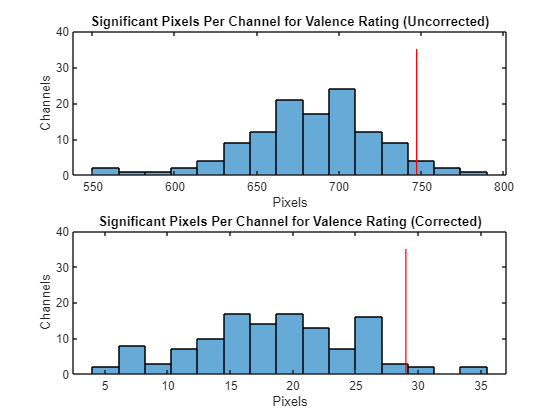


condname = "Valence Rating";
[betas.mask_raw, betas.mask_corr] = mask_pixels(betas, mask_data, 1, condname, 'y');

the call to "ft_selectdata" took 0 seconds


 In ft_singleplotTFR at line 341



the call to "ft_singleplotTFR" took 3 seconds


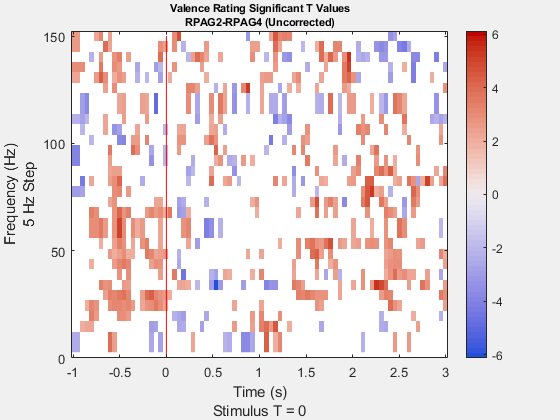

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 1 seconds


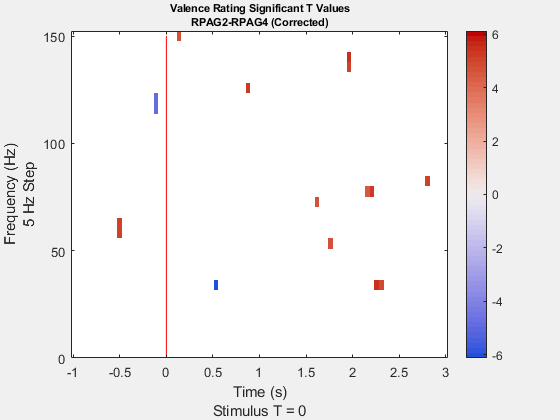

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 1 seconds


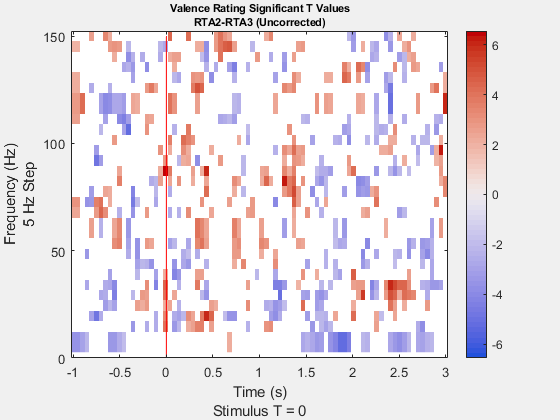

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


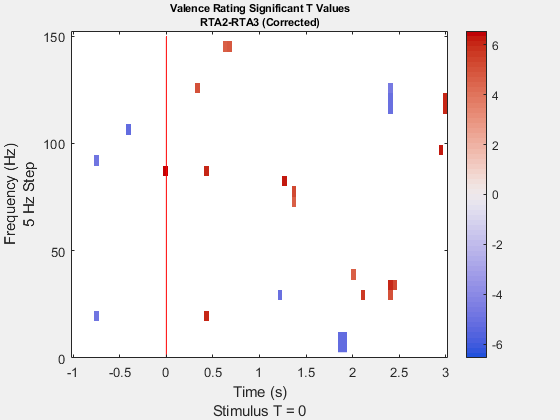

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


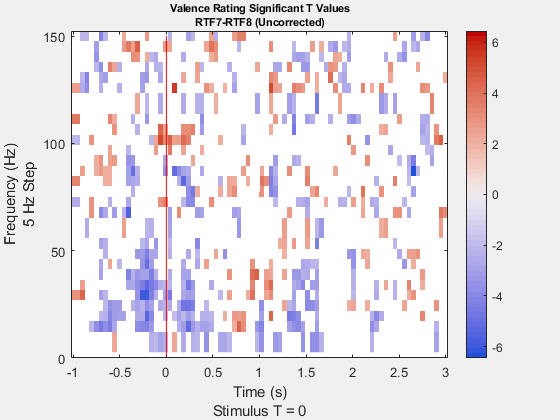

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


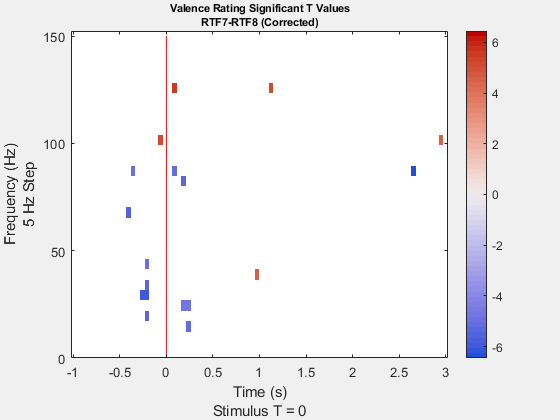

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


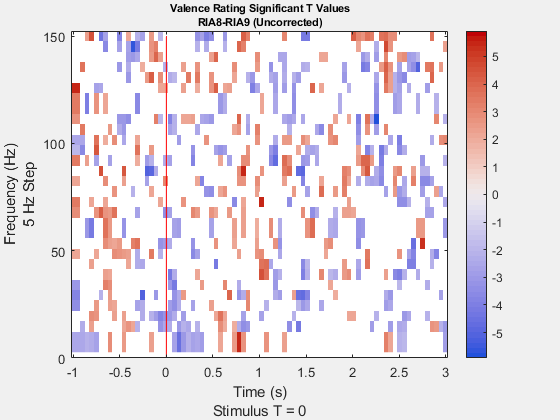

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


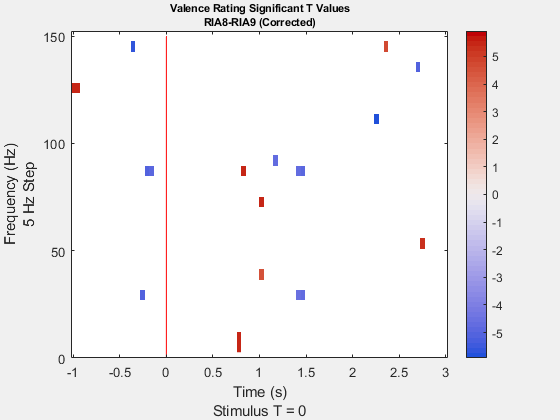

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


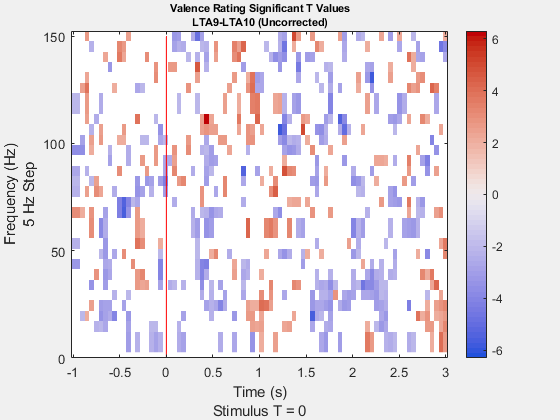

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


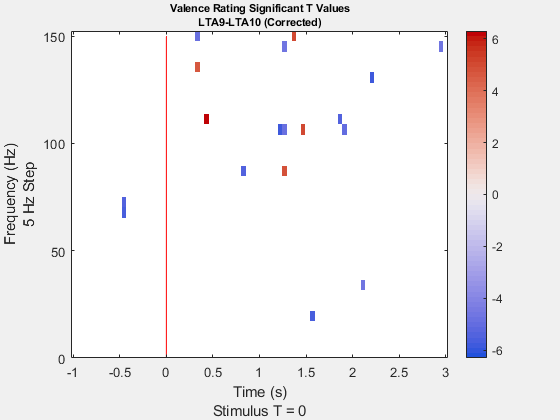


figs = drawsigs(mask_data, betas, condname);

glm = struct();
sigs = struct();
X = design(:,2);
chans = size(imgview_freq.powspctrm, 2);
freqs = size(imgview_freq.powspctrm, 3);
times = size(imgview_freq.powspctrm, 4);
cond = 2;

for j = 1:chans
    for k = 1:freqs
        for l = 1:times


            Y = squeeze(imgview_freq.powspctrm(:,j,k,l));   
            [beta, ~, stats] = glmfit(X,Y);
            
            glm.bmap(j, k,l) = beta(cond);
            glm.tmap(j, k,l) = stats.t(cond);
            glm.pmap(j, k,l) = stats.p(cond);
            if stats.p(cond) < 0.05
                glm.h95(j, k,l) = 1;
            else
                glm.h95(j, k,l) = 0;
            end
            if stats.p(cond) < 0.01
                glm.h99(j, k,l) = 1;
            else
                glm.h99(j, k,l) = 0;
            end
            if stats.p(cond) < 0.001
                glm.h999(j, k,l) = 1;
            else
                glm.h999(j, k,l) = 0;
            end
        
        end
    end
end

data.t_raw = glm.tmap;
data.mask_raw = glm.h95;

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 1 seconds


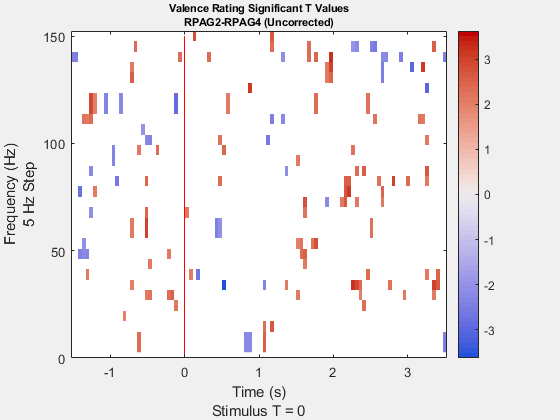

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


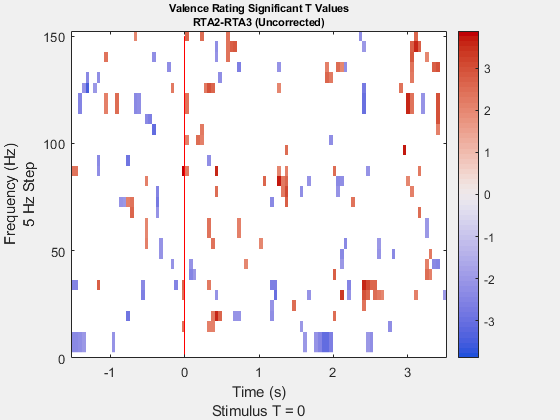

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


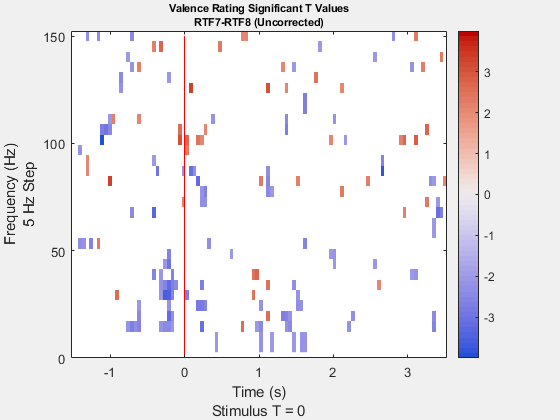

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


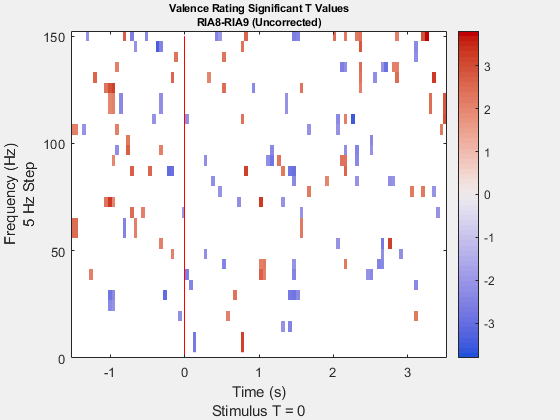

the call to "ft_selectdata" took 0 seconds


the call to "ft_singleplotTFR" took 0 seconds


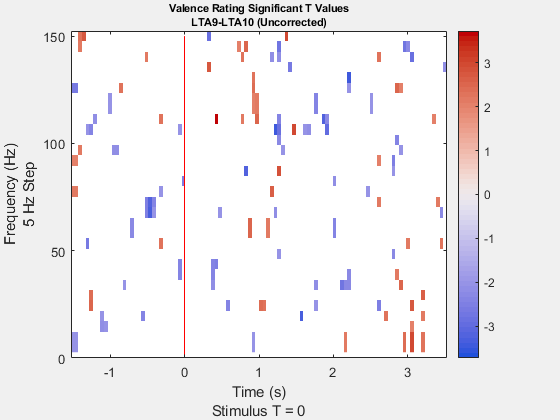


for chan = 1:numel(sigs)
cfg = [];
    cfg.channel = sigs{chan};    
    cfg.parameter = 't_raw';
    cfg.maskparameter = 'mask_raw';
    cfg.colormap = 'coolwarm';
    cfg.figure = 'no';
    % cfg.xlim = [-1 3];

    figure;
    set(gcf, 'Visible', 'on')

    ft_singleplotTFR(cfg, data);
    hold on;
    ylabel({'Frequency (Hz)'; '5 Hz Step'})
    xlabel({'Time (s)'; 'Stimulus T = 0'})
    line([0 0], [0 150], 'Color', 'red'); hold on;
    title({sprintf('%s Significant T Values', condname), sprintf('%s (Uncorrected)', cfg.channel)})
    a = gca; 
    a.CLim = max(abs(a.CLim)) * [-1 1]; % center colormap around 0


   hold off;
end

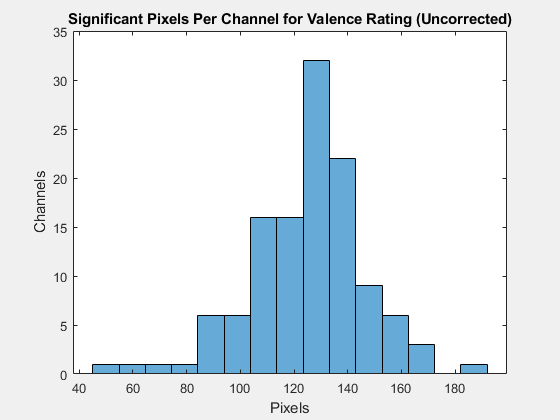

chans = [];
for i = 1:numel(data.label)
chans(i,:) = sum(sum(squeeze(glm.h95(i,:,:))));
end

histogram(chans, 'NumBins', 15); 
    % line([mr.prct95 mr.prct95], [0 35], 'Color', 'red');
    
    xlabel("Pixels")
    ylabel("Channels")
    title(sprintf('Significant Pixels Per Channel for %s (Uncorrected)', condname));

LOCAL FUNCTIONS

function [raw, corr] = mask_pixels(structin, data,  cond, condname, figure)
% Masks pixels based on given structure and data.
% Inputs:
%   - structin: structure from glm_corr
%   - data: data averaged across trials
%   - cond: condition index
%   - condname: name of the condition
%   - figure: flag for plotting
% Outputs:
%   - raw: mask values without FDR
%   - corr: mask values with FDR

s = structin;
if figure ~= 'n'
    figure = 'yes';
end
[n,p] = size(s.cfg.confound);

s.designp = reshape(s.prob(cond+1,:), [], 1);
bsize = size(squeeze(s.prob(cond+1,:,:,:)));
% adj_h_temp = reshape(s.adj_h, [], ); 


% make base.mask_raw
mr = struct();

for i = 1:numel(s.designp)
    % for c = 1:p-1
        if s.designp(i,1) > 0.05
            mr.h(i,1) = 0;
        else
            mr.h(i,1) = 1;
        end
    % end
end
% h_temp = reshape(mr.h(:,1), [], 1);



mr.sig_pix = sum(mr.h);
fprintf('Unthresholded significant voxels: %d \n', mr.sig_pix);
disp(' ')
mr.h_log = mr.h > 0; % for outline mask
disp('');
disp('');
mr.beta = squeeze(structin.beta(cond+1,:,:,:));
mr.t = squeeze(structin.stat(cond+1,:,:,:));
mr.h = reshape(mr.h, bsize);


for i = 1:numel(s.label)
    mr.chans(i,1) = sum(sum(mr.h(i,:,:)));
end
mr.prct95 = prctile(mr.chans, 95);
    


c = 1;
mr.sigchans = {};
for i = 1:numel(s.label)
    channame = s.label{i};
    if sum(sum(mr.h(i,:,:))) > mr.prct95
    
        mr.sigchans{c} = channame;
        c = c + 1;
    end
end
disp(' ')
disp('95th Percentile Uncorrected Channels')
mr.sigchans

raw = mr;
%%%%
mc = struct();
mc.sig_pix = sum(s.adj_h(:,cond));
fprintf('Significant voxels following FDR: %d \n', mc.sig_pix);

mc.h_log = reshape(s.adj_h(:,cond), bsize);
mc.h = double(mc.h_log);


for i = 1:numel(s.label)
    mc.chans(i,1) = sum(sum(mc.h(i,:,:)));
end
mc.prct95 = prctile(mc.chans, 95);
    


c = 1;
mc.sigchans = {};
for i = 1:numel(s.label)
    channame = s.label{i};
    if sum(sum(mc.h(i,:,:))) > mc.prct95
    
        mc.sigchans{c} = channame;
        c = c + 1;
    end
end
disp('95th Percentile Channels Following FDR')
mc.sigchans

corr = mc;

if figure == 'yes'
    subplot(2,1,1);
    histogram(mr.chans, 'NumBins', 15); 
    line([mr.prct95 mr.prct95], [0 35], 'Color', 'red');
    
    xlabel("Pixels")
    ylabel("Channels")
    title(sprintf('Significant Pixels Per Channel for %s (Uncorrected)', condname));
    % fontsize(24, "points")
    
    
    
    
    subplot(2,1,2); 
    histogram(mc.chans, 'NumBins', 15); 
    line([mc.prct95 mc.prct95], [0 35], 'Color', 'red');
    
    xlabel("Pixels")
    ylabel("Channels")
    title(sprintf('Significant Pixels Per Channel for %s (Corrected)', condname));
    % fontsize(24, "points")
    drawnow

    hold off; 
    
end % if figure

end %function



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [cfg] = drawsigs(data, masks, condname)
% Draws significant T values for specified channels.
% Inputs:
%   - data: data with t_raw, mask_raw, and mask_corr
%   - masks: masked data structure

data.t_raw  = masks.mask_raw.t;
data.mask_raw = masks.mask_raw.h;
data.mask_corr = masks.mask_corr.h;
sigchans = masks.mask_raw.sigchans;

cfg = [];
for chan = 1:numel(sigchans)
    cfg.channel = sigchans{chan};    
    cfg.parameter = 't_raw';
    cfg.maskparameter = 'mask_raw';
    cfg.colormap = 'coolwarm';
    cfg.figure = 'no';
    cfg.xlim = [-1 3];

    figure;
    set(gcf, 'Visible', 'on')

    ft_singleplotTFR(cfg, data);
    hold on;
    ylabel({'Frequency (Hz)'; '5 Hz Step'})
    xlabel({'Time (s)'; 'Stimulus T = 0'})
    line([0 0], [0 150], 'Color', 'red'); hold on;
    title({sprintf('%s Significant T Values', condname), sprintf('%s (Uncorrected)', cfg.channel)})
    a = gca; 
    a.CLim = max(abs(a.CLim)) * [-1 1]; % center colormap around 0


   hold off;

    cfg.maskparameter = 'mask_corr';
    cfg.figure = 'no';
    figure;    
    set(gcf, 'Visible', 'on')

    ft_singleplotTFR(cfg, data);
    hold on;
    ylabel({'Frequency (Hz)'; '5 Hz Step'})
    xlabel({'Time (s)'; 'Stimulus T = 0'})
    line([0 0], [0 150], 'Color', 'red'); hold on;
    title({sprintf('%s Significant T Values', condname), sprintf('%s (Corrected)', cfg.channel)})
    a = gca; 
    a.CLim = max(abs(a.CLim)) * [-1 1]; % center colormap around 0

   pause(0.5)

end

end
